### Loading dataset

dpath = 'restaurantLab_ExtMR.xlsx'; % dataset path

T = readtable(dpath, 'ReadVariableNames',true, 'ReadRowNames',true);

Converting categorical variables.

T.DayType = categorical(T.DayType, 'Ordinal', true);
T.Area = categorical(T.Area, 'Ordinal', true);

#### Plotting Daily Sales

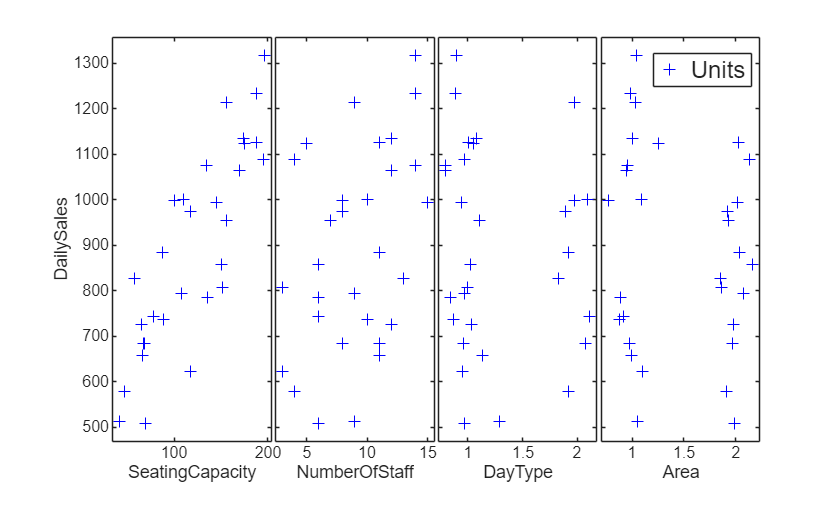

yXplot(T(:, "DailySales"), T(:, 2:end));

The yXplot shows that the **SeatingCapicity** has the strongest relationship with **DailySales**, which obviously means bigger outlets make more daily sales than small ones. Moreover, it illustrates **weekdays** produce more sales than **weekends** (which is insane, but interesting huah!) and most probably outlets in **downtown** have more sales in contrast with the ones in **suburb**.

### Full Multiple Regression Model

% fitting the model
mdl = fitlm(T, "DailySales");